# Opgave 1

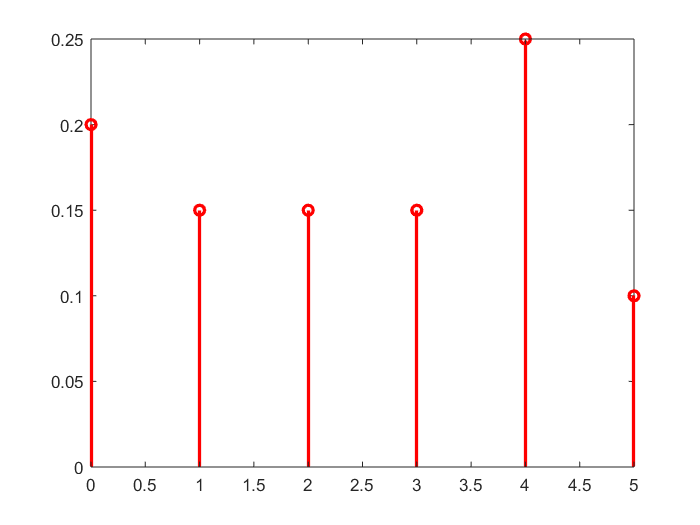

clearvars
% B
x = 0:1:5;
y = [0.2, 0.15, 0.15, 0.15, 0.25, 0.10];
stem(x,y,'-r','LineWidth',2)

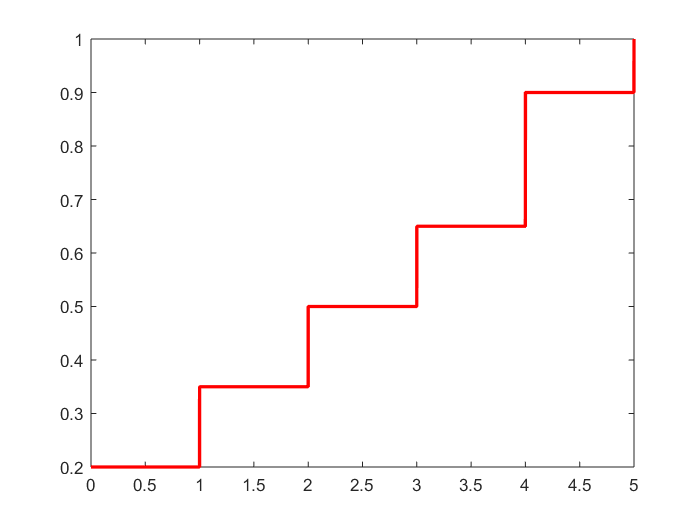

% B 
clearvars
syms x
y = piecewise(x < 0, 0, ...
    0 <= x < 1, 0.2, ... 
    1 <= x < 2, 0.2+0.15, ...
    2 <= x < 3, 0.2+0.15+0.15, ...
    3 <= x < 4, 0.2+0.15+0.15+0.15, ...
    4 <= x < 5, 0.2+0.15+0.15+0.15+0.25, ...
    5 <= x, 0.2+0.15+0.15+0.15+0.25+0.1);
fplot(y,[0,5], '-r','LineWidth',2)

% C
clearvars
x = 0:1:5;
y = [0.2, 0.15, 0.15, 0.15, 0.25, 0.10];
Ex = sum(x.*y)

Ex = 2.4000

Ex2 = sum((x.^2).*y)

Ex2 = 8.6000

var = Ex2 - Ex^2

var = 2.8400

## Opgave 2

% A
format rat
1 - (5/25) - (7/25) - (7/25) - (3/25)

ans =        3/25    


% D
(3/25) / (7/25)

ans =        3/7     


## Opgave 3

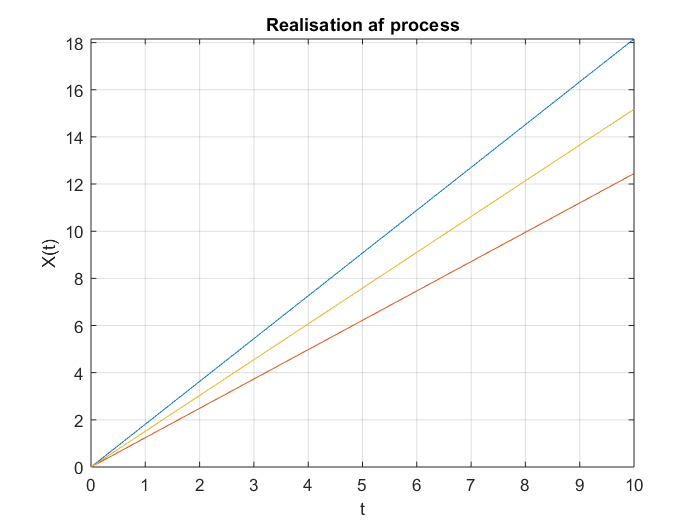

clearvars
close all
R = 3; % Antal realisationer
N = 10; % Antal samples
mean = 1; variance=(1/4); sigma=sqrt(variance);
% a = normrnd(MU,SIGMA,[M,N,...]) returns an M-by-N-by-... array 
% of random numbers chosen from a normal distribution 
% with mean MU and standard deviation SIGMA.
a = normrnd(mean, sigma, [1 R]);
syms t
figure()
y = a*t;
fplot(y,[0 10])
hold on
grid on;
xlabel("t"); ylabel("X(t)"); title("Realisation af process");

## Opgave 4

format short
lambda = 25;
test = poisscdf(30, lambda)

test = 0.8633

Pr_30 = 1-poisscdf(30,lambda)

Pr_30 = 0.1367

% b
Pr_80 = poisscdf(80,4*lambda)

Pr_80 = 0.0226